# brushPlot

#### Load brush stimulation file

[filenameMat,pathMat] = uigetfile('Z:\GintyLab\Qi\stimulation\brush\*.mat');
load([pathMat,filenameMat])

#### Plot together

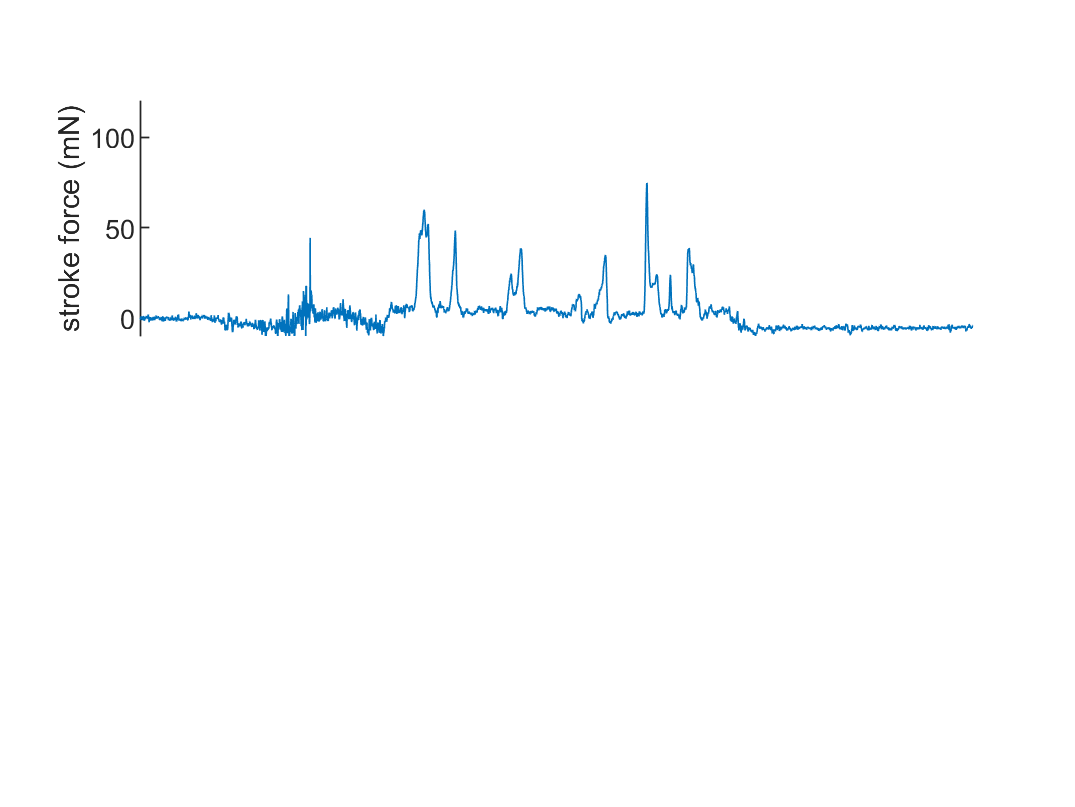

figure,
brushForce = (data-0.9155) / 0.1357 * 9.8;
brushForce = brushForce - median(brushForce);

sfh1 = subplot(211);
line(time,brushForce);
ylim([-10, 120]);
ylabel('stroke force (mN)')
xlabel('time (s)');
set(gca,'xcolor',[1 1 1])
sfh1.Position = sfh1.Position - [0 0 0 0.05];

%pbaspect([3 1 1]);
%set(gcf, 'Position', [100, 100, 1500, 500]);

% get the neuron
nCell = input('the neuron you are interesed in?  \n ');

normDeltaFncell = normDeltaF(:,nCell);

sfh2 = subplot(212);
%sfh2.Position = sfh2.Position + [0 0 0 0.05];
x = 1:length(normDeltaFncell);
line(x,normDeltaFncell);
xlim([1,length(time)/Fs*fps])
ylabel('\DeltaF/F')
xticks([20*fps:20*fps:length(time)/Fs*fps]);
TickinSec = num2str(time(20*Fs+1:20*Fs:end));
xticklabels(TickinSec);
xlabel("time (s)")
title(strcat('Neuron', {' '} ,num2str(nCell)));


#### plot by heat map

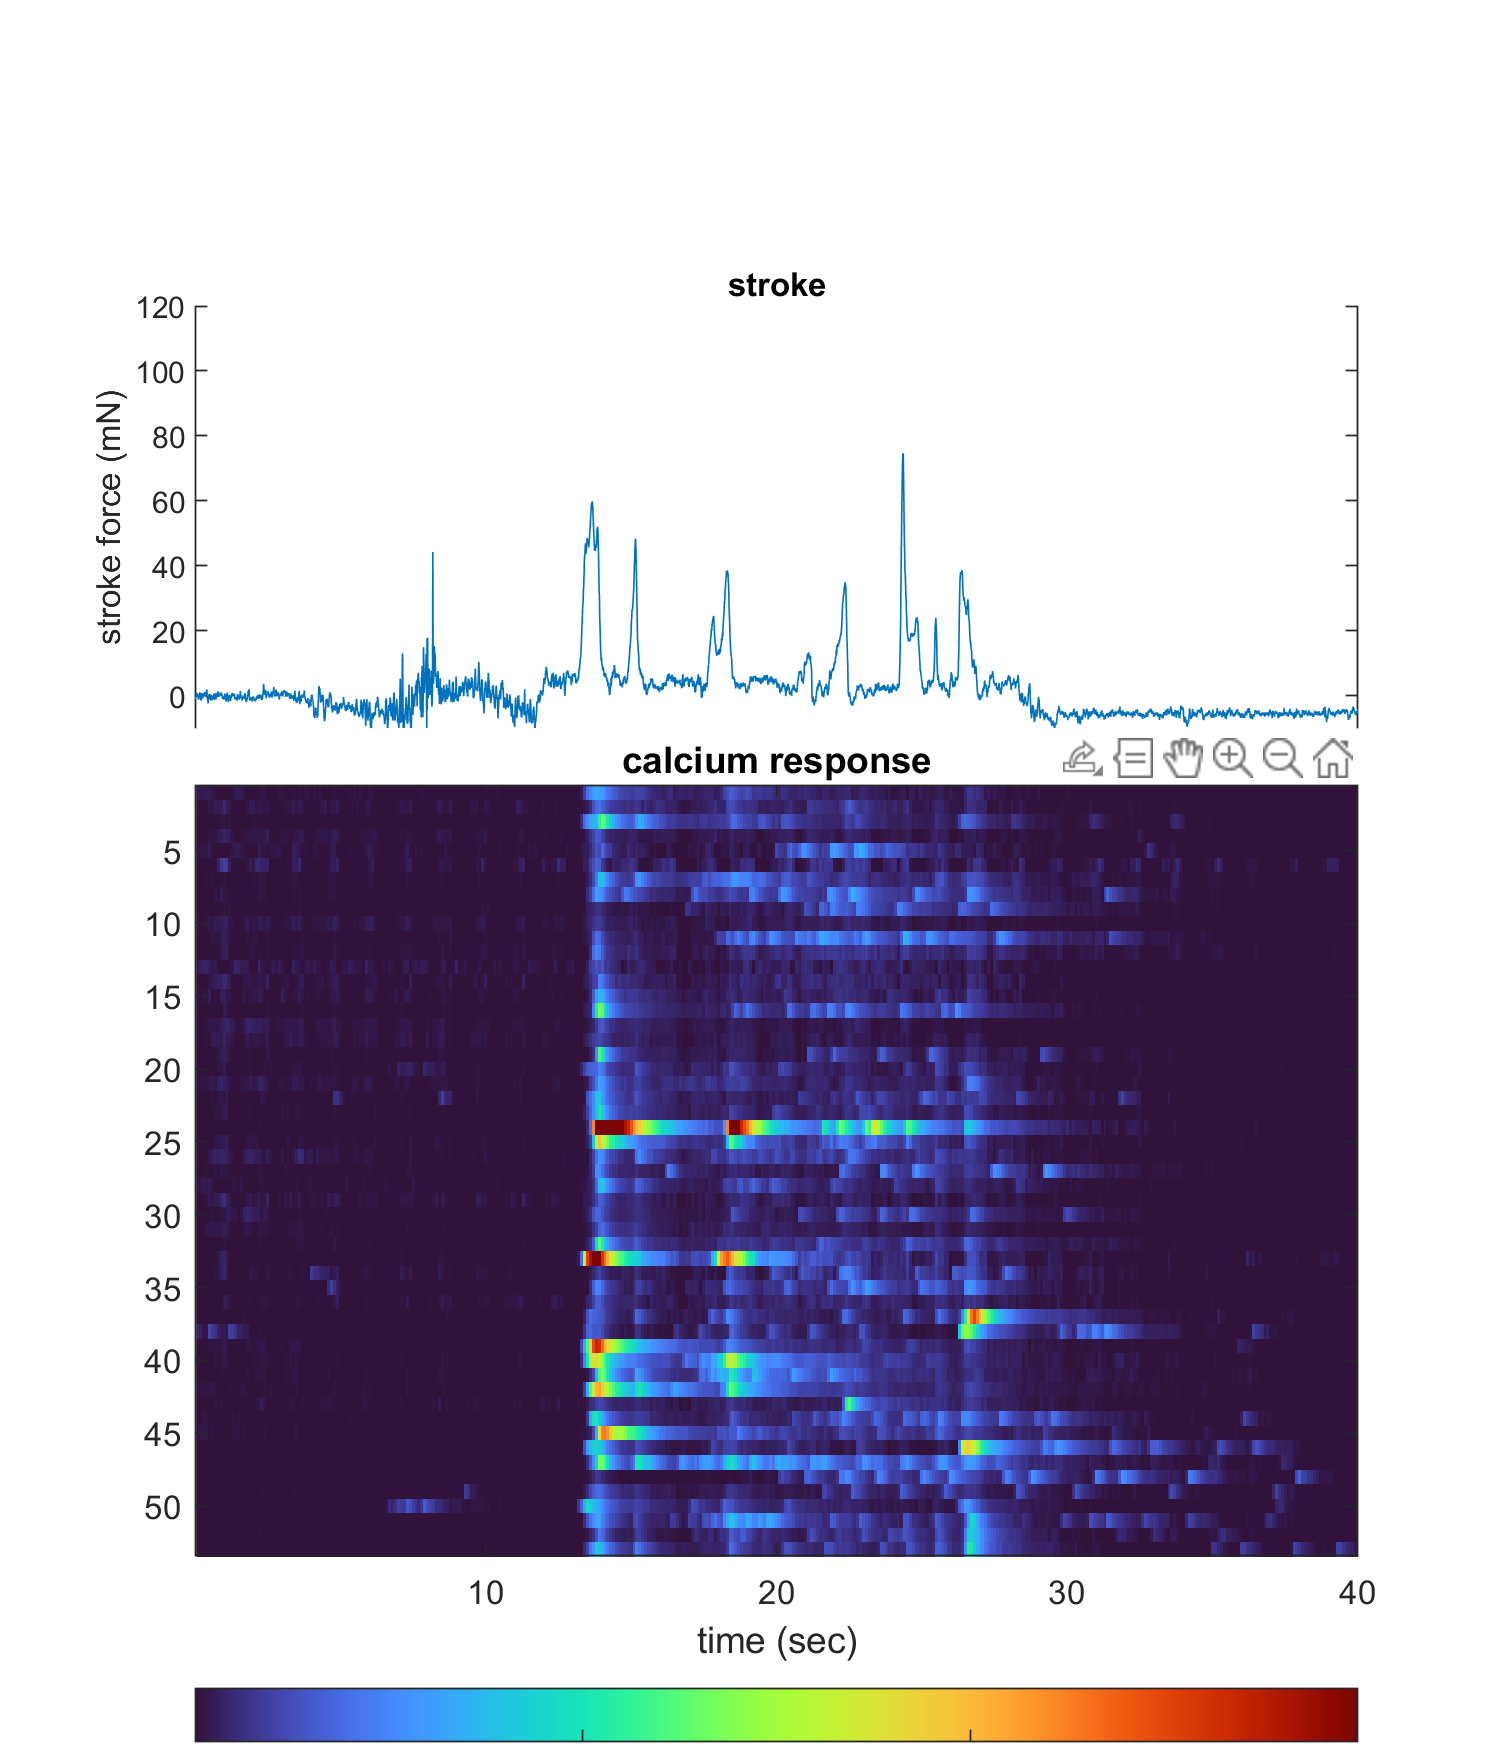

fh = figure;
set(gcf,'Visible','on')
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.3, 0.6]);
set(gcf, 'Position',  [400, 100, 600, 700])

brushStart = 0 ; % (in sec) at the start of brush, sensor could be noisy before brushing,
% choose a starting point to cut out the noisy part

brushForce = (data-0.9155) / 0.1357 * 9.8;
brushForce = brushForce - median(brushForce);

sfh1 = subplot(211);
%plot(brushForce(brushStart*Fs/fps:end));
plot(brushForce)
ylim([-10, 120]);
%xlim()
xlim([brushStart*Fs/fps, length(brushForce)]);
ylabel('stroke force (mN)'),
set(gca,'xcolor',[1 1 1])
sfh1.Position = sfh1.Position - [0 0 0 0.1];
title("stroke")

sfh2 = subplot(212);
% imagesc(normDeltaF(:,find(sum(digitROI)))'),
imagesc(normDeltaF'),
colormap(turbo),
colorbar('southoutside'); set(gcf,'color','w');
% play with the colorbar scale
Max = sort(max(normDeltaF)); MaxLimit = mean(Max(end-4:end));
if MaxLimit > 1.5 || MaxLimit < 0.2
    Limit = 1.5;
else
    Limit = MaxLimit;
end


xticks(100:100:length(time)/Fs*fps)
timelabel = strsplit(num2str([100:100:length(time)/Fs*fps]/fps));
xticklabels(timelabel);
xlabel('time (sec)')

%caxis([0 Limit])
caxis([0 1.5])
xlim([brushStart,length(time)/Fs*fps])

sfh2.Position = sfh2.Position + [0 0 0 0.1];
title("calcium response")